# The Tacoma Narrows Bridge Disaster

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Task 1

Find and plot the road oscillations for the first 1000 seconds of motion.

*Remember to define your ODE function at the bottom of the script. *

The angle that the road makes with the horizontal *θ*(*t*)  can be determined by solving the following second-order ODE:

*d^*2*θ/d**t^*2=−0.01*d**θ/d**t*−2.4cos*θ*sin*θ*+0.05sin(1.3*t*)

with initial conditions

*θ*(0)=1.2 radians

*d**θ/d**t*(0)=*ω*(0)=0 rad/s

tRange = [0 1000];
Y0 = [1.2; 0];
[tSol, YSol] = ode45(@tacomaNarrows, tRange, Y0);

## Task 2

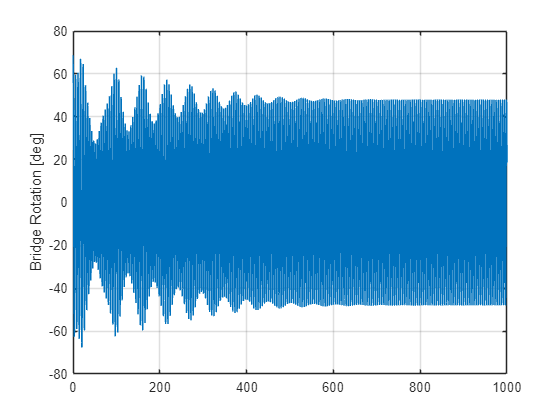

Theta = YSol(:, 1)*180/pi;
plot(tSol, Theta)
grid on
ylabel("Bridge Rotation [deg]")

## Task 1 (continued)

Define the ODE function for   

function dYdt = tacomaNarrows(t, Y)
    % Extract the position Theta from the first element of Y.
    Theta = Y(1);
    
    % Extract the angular velocity Omega from the second element of Y.
    Omega = Y(2);
    
    % Complete expression for dxdt
    dThetadt = Omega;
    
    % Complete expression for dvdt
    dOmegadt = -0.01*Omega - 2.4*cos(Theta)*sin(Theta) + 0.05*sin(1.3*t);
    
    % Store derivatives to output vector
    dYdt = [dThetadt; dOmegadt];
end